 **Practical Problems 6 – Matrices & Systems of Equations**	 	 

1.Use the **eye** function to create a 4 x 5 diagonal matrix called ***A*** with 7’s on the leading diagonal.

A = eye(4, 5)

A =      1     0     0     0     0
     0     1     0     0     0
     0     0     1     0     0
     0     0     0     1     0


A = 7 .* A

A =      7     0     0     0     0
     0     7     0     0     0
     0     0     7     0     0
     0     0     0     7     0


2.Create a 3 x 3 elementary matrix called ***E*** that adds 3 of the 1st row to the 3rd row of a matrix. Test it with a random 3 x 3 matrix of integers.

E = eye(3)

E =      1     0     0
     0     1     0
     0     0     1


E(3, 1) = 3  % Adding 3 times the 1st row to the 3rd row

E =      1     0     0
     0     1     0
     3     0     1



% Test with a random 3x3 matrix of integers
randomMatrix = randi([1, 10], 3, 3)  % Generating a random 3x3 matrix with values between 1 and 10

randomMatrix =      9    10     8
     6     3     4
     6     8     6


resultMatrix = E * randomMatrix

resultMatrix =      9    10     8
     6     3     4
    33    38    30


3.Augment the test matrix from question 2 with a 3 x 3 identity matrix then use Matlab’s **rref** function to find it’s reduced echelon form.	

% Given test matrix and elementary matrix E from previous steps
testMatrix = randomMatrix;  % Using the random matrix from before
E = eye(3);
E(3, 1) = 3

E =      1     0     0
     0     1     0
     3     0     1



% Augment the test matrix with a 3x3 identity matrix
augmentedMatrix = [testMatrix, eye(3)]

augmentedMatrix =      9    10     8     1     0     0
     6     3     4     0     1     0
     6     8     6     0     0     1



% Apply the elementary matrix operation to the augmented matrix
augmentedMatrix = E * augmentedMatrix

augmentedMatrix =      9    10     8     1     0     0
     6     3     4     0     1     0
    33    38    30     3     0     1



% Find the reduced row echelon form (rref) of the augmented matrix
rrefMatrix = rref(augmentedMatrix)

rrefMatrix =     1.0000         0         0    2.3333   -0.6667   -2.6667
         0    1.0000         0    2.0000   -1.0000   -2.0000
         0         0    1.0000   -5.0000    2.0000    5.5000


4.Create the coefficient matrix for the following linear system, check that its determinant is not 0, then calculate the solution using the inverse matrix method (*hint:* you can find the inverse of a matrix with the **inv** function).                                         

3*x1 + 4*X2 = 3

5*x1 + 6*x2 = 7

x = A^-1b

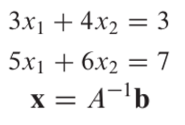

% Coefficient matrix A and constant vector b
A = [3, 4; 5, 6]

A =      3     4
     5     6


b = [3; 7]

b =      3
     7



% Check determinant of A
detA = det(A);
if detA == 0
    disp("The determinant of the coefficient matrix A is 0. The system may not have a unique solution.")
else

    % Calculate the inverse of A
    A_inv = inv(A);
    
    % Calculate the solution using inverse matrix method
    x = A_inv * b;
    
    disp("The solution is:");
    disp(x);
end

The solution is:


    5.0000
   -3.0000



5.Solve the system above but using Matlab’s left-division operator.

% Coefficient matrix A and constant vector b
A = [3, 4; 5, 6];
b = [3; 7];

% Solve the system using left-division operator
x = A \ b;

disp("The solution is:");

The solution is:


disp(x);

    5.0000
   -3.0000



6.There are 3 reactors linked by pipes as shown below. The rate of transfer of chemicals through each pipe is equal to a flow rate (Q, with units of cubic meters per ­second) multiplied by the concentration of the reactor from which the flow originates (c, with units of milligrams per cubic meter). If the system is at a steady state, the transfer into each reactor will balance the transfer out. Develop mass-balance equations for the reactors and solve the three simultaneous linear algebraic equations for their concentrations.                   

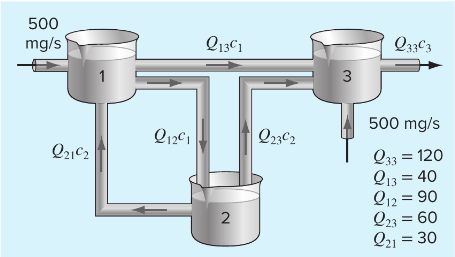

A = [130, -30, 0 ; 90, -90, 0 ; -40, -60, 120];
b = [500 ; 0 ; 500];

% Check determinant of A
detA = det(A);
if detA == 0
    disp("The determinant of the coefficient matrix A is 0. The system may not have a unique solution.")
else

    % Calculate the inverse of A
    A_inv = inv(A);
    
    % Calculate the solution using inverse matrix method
    x = A_inv * b;
end
fprintf('The value of c1 is %.4f\n', x(1, :));

The value of c1 is 5.0000


fprintf('The value of c2 is %.4f\n', x(2, :));

The value of c2 is 5.0000


fprintf('The value of c3 is %.4f\n', x(3, :));

The value of c3 is 8.3333


7.Use Matlab’s **fsolve** function to find the roots of the system. Since there are infinite solutions you do not need to find every root. Just locate and plot those given in the default window. Plotting is always a good idea to give you an idea of how many roots you are looking for and where to make the initial guesses. Use the **fimplicit** function to plot these implicit functions on the same graph. Define a function at the end of your script closed with keyword **end** that holds the system of equations. Advanced users can also use the ginput() function to pick starting initial guesses.                                            

exp(xy) - y.^2 = 0

cos(x+y) = 0

% Define the system of equations function

% f = @(x) exp(x(1) * x(2)) - x(2)^2;
% g = @(x) cos(x(1) + x(2));

% Use fsolve to find the roots of the system
initialGuesses = [0.5, 5; 0.5, 0.5; -0.5, 0.5; -0.5, -5; -0.5, -0.5; 2, -0.5]

initialGuesses =     0.5000    5.0000
    0.5000    0.5000
   -0.5000    0.5000
   -0.5000   -5.0000
   -0.5000   -0.5000
    2.0000   -0.5000


roots = [];

for i = 1:size(initialGuesses, 1)
    root = fsolve(@equations, initialGuesses(i, :));
    roots = [roots; root];
end


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the 

disp("Roots found:");

Roots found:


disp(roots);

    0.6922    4.0202
    0.3387    1.2320
   -2.1254    0.5546
   -0.6922   -4.0202
   -0.3387   -1.2320
    2.1254   -0.5546



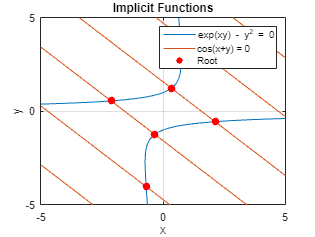


% Define the implicit functions for plotting
fimplicit(@(x, y) exp(x .* y) - y.^2, [-5, 5, -5, 5]);
hold on;
fimplicit(@(x, y) cos(x + y), [-5, 5, -5, 5]);
scatter(roots(:, 1), roots(:, 2), 50, 'ro', 'filled');
hold off;

xlabel('x');
ylabel('y');
title('Implicit Functions');
legend('exp(xy) - y^2 = 0', 'cos(x+y) = 0', 'Root');
grid on;

8.Find a root of the following system. Check your solution.                                    

3*x - cos(y*z) = 3/2

4* x.^2 - 625*y.^2 + 2*z = 1

20*z + exp(-x*y) = -9

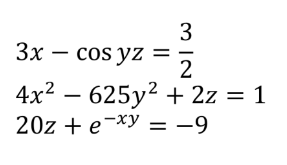

% Use fsolve to find a root
initialGuess = [0, 0, 0];
[x_sol, fval, exitflag] = fsolve(@myEquations, initialGuess)


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


x_sol =     0.8333   -0.0352   -0.5015


fval = 1.0e-12 *

         0   -0.1357         0


exitflag = 1

%x_sol is the output variable where the solution to the system of equations is stored. x_sol contains the values of x, y, and z.
%fval is the output variable that contains the values of the equations evaluated at the solution x_sol.
%exitflag is the output variable that indicates the exit condition of the solver. 
% A positive exitflag typically indicates a successful convergence to a solution, while a negative value may indicate issues or failure to find a solution.

x = x_sol(1);
y = x_sol(2);
z = x_sol(3);

% Check the solution
if exitflag > 0
    fprintf('Root found:\n');
    fprintf('x = %.6f\n', x);
    fprintf('y = %.6f\n', y);
    fprintf('z = %.6f\n', z);
else
    fprintf('No root found or an error occurred.\n');
end

Root found:


x = 0.833281


y = -0.035201


z = -0.501488


% Evaluate the equations with the solution
eq1 = 3 * x - cos(y * z) - 3/2;
eq2 = 4 * x^2 - 625 * y^2 + 2 * z - 1;
eq3 = 20 * z + exp(-x * y) + 9;

fprintf('Substituting into the first equation gives: %e\n', eq1);

Substituting into the first equation gives: 0.000000e+00


fprintf('Substituting into the second equation gives: %e\n', eq2);

Substituting into the second equation gives: -1.356693e-13


fprintf('Substituting into the third equation gives: %e\n', eq3);

Substituting into the third equation gives: 0.000000e+00


9.Write a script that uses the Newton Method for Nonlinear Systems to solve the following nonlinear system. Try to find the roots of the system with your script. Remember you’ll have to compute the Jacobian yourself by hand for now in order to put it into your script.                    

(3*x .^ 2) + (2 * y .^ 2) = 25

(x*x .^ 2) - y = 15                    

% Define the symbolic variables
syms x y;

% Define the equations
eq1 = 3*x^2 + 2*y^2 - 25;
eq2 = 2*x^2 - y - 15;

% Create the vector-valued function F
F = [eq1; eq2];

% Initialize the roots array
roots = [];

initial_guesses = [1, 1; -1, 1; -1, -1; 1, -1];

for i = 1:size(initial_guesses, 1)
    x0 = initial_guesses(i, :)';
    
    % Tolerance for convergence
    tolerance = 1e-6;

    % Maximum number of iterations
    maxIterations = 100;

    % Initialize the Jacobian matrix
    Jacobian = jacobian(F, [x, y]);

    % Start the Newton-Raphson iteration
    for iter = 1:maxIterations
        % Calculate the value of F and Jacobian at the current point
        F_value = double(subs(F, [x; y], x0));
        J_value = double(subs(Jacobian, [x; y], x0));

        % Solve the linear system to get the update
        delta = -J_value \ F_value;

        % Update the current point
        x0 = x0 + delta;

        % Check for convergence
        if norm(delta) < tolerance
            roots = [roots; x0'];
            break;
        end
    end
end
% Display the roots
fprintf('The roots are:\n');

The roots are:


disp(roots);

    2.8111    0.8042
   -2.8111    0.8042
   -2.5929   -1.5542
    2.5929   -1.5542



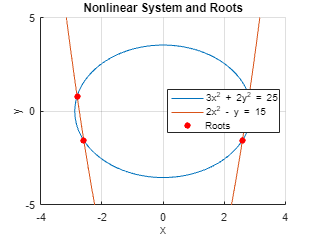


% Create a plot
figure;
hold on;
fimplicit(eq1);
fimplicit(eq2);

% Plot the roots
scatter(roots(:, 1), roots(:, 2), 'ro', 'filled');

xlabel('x');
ylabel('y');
title('Nonlinear System and Roots');
legend('3x^2 + 2y^2 = 25', '2x^2 - y = 15', 'Roots', 'Location', 'Best');
grid on;

hold off;

10.Write a script that reduces a 3 x 3 matrix to an echelon form (don’t worry about pivoting). Test it on the following matrix:          

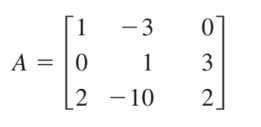                       

% Given matrix
A = [1, -3, 0; 0, 1, 3; 2, -10, 2];
disp('Original matrix:');

Original matrix:


disp(A);

     1    -3     0
     0     1     3
     2   -10     2




[m, n] = size(A);  % Size of the matrix

for i = 1:min(m, n)
    % Perform row operations to create zeros below the pivot element
    for j = i+1:m
        factor = A(j, i) / A(i, i);
        A(j, :) = A(j, :) - factor * A(i, :);
    end
end

disp('Matrix in echelon form:');

Matrix in echelon form:


disp(A);

     1    -3     0
     0     1     3
     0     0    14



11.Write a script that reduces the above matrix to reduced echelon form (RREF).

% Given matrix
A = [1, -3, 0; 0, 1, 3; 2, -10, 2];
disp('Original matrix:');

Original matrix:


disp(A);

     1    -3     0
     0     1     3
     2   -10     2




[m, n] = size(A);  % Size of the matrix

for i = 1:m
    % Divide the current row by the pivot element to make it 1
    A(i, :) = A(i, :) / A(i, i);
    
    % Perform row operations to make other entries in the column zero
    for j = 1:m
        if j ~= i
            factor = A(j, i);
            A(j, :) = A(j, :) - factor * A(i, :);
        end
    end
end

disp('Matrix in reduced echelon form (RREF):');

Matrix in reduced echelon form (RREF):


disp(A);

     1     0     0
     0     1     0
     0     0     1



12.Write a script that finds the LU factorisation of the matrix ***A*** in question 10 using Gaussian elimination to find ***U*** and the formulae given in lecture notes 6 to find ***L***.

A = [1, -3, 0; 0, 1, 3; 2, -10, 2];
[n, ~] = size(A);

% Initialize L as an identity matrix
L = eye(n);

% Initialize U as a copy of A
U = A;

% Perform Gaussian elimination to find U and the elements of L
for k = 1:n-1
    for i = k+1:n
        % Calculate the multiplier for the elimination
        L(i, k) = U(i, k) / U(k, k);
        
        % Update the elements of U and L
        U(i, k:n) = U(i, k:n) - L(i, k) * U(k, k:n);
    end
end

% Display the matrices L and U
fprintf('Matrix L:\n');

Matrix L:


disp(L);

     1     0     0
     0     1     0
     2    -4     1



fprintf('Matrix U:\n');

Matrix U:


disp(U);

     1    -3     0
     0     1     3
     0     0    14



13.Solve the following system using LU factorisation by finding ***L*** and ***U*** as in question 13.                             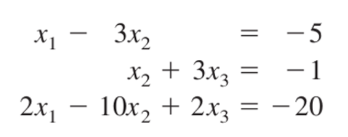

% Define the right-hand side vector
b = [-5; -1; -20];

% Solve Ly = b using forward substitution
n = length(b);
y = zeros(n, 1);

y(1) = b(1) / L(1, 1);
for i = 2:n
    y(i) = (b(i) - L(i, 1:i-1) * y(1:i-1)) / L(i, i);
end

% Solve Ux = y using backward substitution
x = zeros(n, 1);

x(n) = y(n) / U(n, n);
for i = n-1:-1:1
    x(i) = (y(i) - U(i, i+1:n) * x(i+1:n)) / U(i, i);
end

% Display the solution
fprintf('Solution:\n');

Solution:


disp(x);

     1
     2
    -1



14Solve the above system using LU factorisation but use Matlab’s built in** lu** function. Note you must account for the permutation matrix given by Matlab.

A = [10 6 10 4 -7; -7 -8 3 5 4; 10 -2 -10 5 -10; 10 9 7 -2 -5; 0 6 9 3 -10];
disp("Matrix A");

Matrix A


A

A =     10     6    10     4    -7
    -7    -8     3     5     4
    10    -2   -10     5   -10
    10     9     7    -2    -5
     0     6     9     3   -10


A_inverse = calculate_inverse(A);

Unrecognized function or variable 'calculate_inverse'.

disp("The invers is A^(-1)");
A_inverse
check = A * A_inverse;
disp("Check A*A_inverse");
check

**15.Challenge Problem**Write your own function file that calculates the inverse of a square matrix. The input should be a square matrix of any size and it should have sufficient checks to make sure the user inputs an invertible matrix or return an error/warning.	

function F = equations(x)
    F = [exp(x(1) * x(2)) - x(2).^2;
         cos(x(1) + x(2))];
end

function F = myEquations(X)
    x = X(1);
    y = X(2);
    z = X(3);

    F(1) = 3 * x - cos(y * z) - 3/2;
    F(2) = 4 * x^2 - 625 * y^2 + 2 * z - 1;
    F(3) = 20 * z + exp(-x * y) + 9;
end

function inverse_matrix = calculate_inverse(matrix)
    % Check if the input matrix is square
    [m, n] = size(matrix);
    if m ~= n
        error('Input matrix must be square.');
    end
    
    % Check if the determinant of the matrix is zero
    if abs(det(matrix)) < eps
        error('Matrix is not invertible (determinant is zero).');
    end
    
    % Calculate the inverse using MATLAB's built-in function
    inverse_matrix = inv(matrix);
end